Cargar parámetros del filtro (Especificaciones)

if exist('PDS_P5_3A_LE2_G4.mat', 'file')
    load('PDS_P5_3A_LE2_G4.mat');
    fprintf('Parámetros cargados: M=%d, Fs=%.0f, Fpass=%.0f, Apass=%.1f, Astop=%.1f\n', ...
            M, Fs, f, Apass, Astop);
else
    error('El archivo PDS_P5_3A_LE2_G4.mat no se encuentra en la carpeta actual.');
end

1. Cuantificación de los coeficientes de un filtro

a) Obtenga los coeficientes a y b de un filtro IIR paso bajo con las siguientes características: Tipo: Lowpass, Método: Elliptic, Orden: M, Fs: Fs, Fpass: f, Apass: Apass, Astop: Astop.

Procedemos a crear el filtro escribiendo en la línea de comandos 'fdatool'.

De ahí obtenemos los coeficientes, los cuales están subidos como 'coeficientes.mat'.

% Cargar coeficientes del filtro (b y a)
if exist('coeficientes.mat', 'file')
    load('coeficientes.mat');
    disp('Coeficientes b (numerador) y a (denominador) cargados correctamente.');
    % Mostrar tamaño de los vectores para verificar
    fprintf('Longitud de b: %d, Longitud de a: %d\n', length(b), length(a));
else
    error('El archivo coeficientes.mat no se encuentra en la carpeta actual.');
end

Coeficientes b (numerador) y a (denominador) cargados correctamente.


Longitud de b: 9, Longitud de a: 9


b) Cuantifique los coeficientes a y b con B = 16 bits, de los cuales D = 8 bits corresponden a la parte decimal. Use las propiedades ‘fixed’, ‘round’ y ‘saturate’ de la función quantizer.

% D = 8 bits (parte decimal), B = 16 bits
% I = 7

q = quantizer('fixed', 'round', 'saturate', [16, 8]);
a_q = quantize(q,a);
b_q = quantize(q,b);

Como se verá más adelante, al cuantificar, cambia por completo la respuesta en frecuencia.

Se han podido mover los ceros (crecida la distancia entre el vector y la circunferencia unidad). Con la fase, perdemos esos saltos de fase.

Como tenía pocos bits, lo he perdido. NO tengo la suficiente precisión para poder representar la posición de los ceros que estaban originalmente en la circunferencia unidad.

2. Secciones de Segundo Orden (SOS)

a) Calcule las Secciones de Segundo Orden del filtro IIR diseñado en el bloque anterior mediante la función tf2sos.

Con el objetivo de reducir el efecto de la cuantificación de los coeficientes del filtro IIR diseñado, se procede a su descomposición en Secciones de Segundo Orden (SOS). Este método permite que cada coeficiente afecte únicamente a una raíz o a un par de raíces complejas conjugadas, mejorando así la robustez del filtro frente a errores de cuantificación.

A partir de los coeficientes del numerador b y del denominador a, calculados en el bloque anterior, se han obtenido las Secciones de Segundo Orden utilizando la función tf2sos de Matlab, que devuelve la matriz sos y una ganancia asociada g.

% Cargar coeficientes del filtro original
load PDS_P5_3A_LE2_G4.mat
load coeficientes.mat   % variables: b (numerador) y a (denominador)

% Cálculo de las Secciones de Segundo Orden
[sos, g] = tf2sos(b, a);

disp('Matriz de Secciones de Segundo Orden (sos):');

Matriz de Secciones de Segundo Orden (sos):


disp(sos);

    1.0000    1.0322    1.0000    1.0000   -1.4506    0.5348
    1.0000   -0.8412    1.0000    1.0000   -1.5104    0.6372
    1.0000   -1.3442    1.0000    1.0000   -1.6007    0.7820
    1.0000   -1.4835    1.0000    1.0000   -1.7051    0.9269




% Estructura de sos:
%Cada fila tiene la forma:
% [b0i b1i b2i 1 a1i a2i]

disp('Ganancia asociada al filtro:');

Ganancia asociada al filtro:


disp(g);

   3.6041e-04



b) Cuantifique cada uno de los coeficientes de la matriz de Secciones de Segundo Orden con el mismo cuantificador empleado en el bloque anterior (B = 16 bits, D = 8 bits).

Posteriormente, se han cuantificado todos los coeficientes de la matriz de Secciones de Segundo Orden empleando un cuantificador de tipo fijo con 16 bits totales, de los cuales 8 corresponden a la parte fraccionaria, utilizando redondeo y saturación. La cuantificación se ha realizado coeficiente a coeficiente para cada sección.

Finalmente, se ha comparado la respuesta en frecuencia del filtro original expresado en SOS con la del filtro cuyas Secciones de Segundo Orden han sido cuantificadas, observándose una menor degradación de la respuesta en comparación con la cuantificación directa de los coeficientes a y b.

% Parámetros del cuantificador
B = 16;   % bits totales
D = 8;    % bits decimales

q = quantizer('fixed', 'round', 'saturate', [B D]);

% Inicialización
sos_q = zeros(size(sos));

% Cuantificación de cada coeficiente SOS
for i = 1:size(sos,1)
    for j = 1:size(sos,2)
        sos_q(i,j) = bin2num(q, num2bin(q, sos(i,j)));
    end
end

disp('Matriz SOS cuantificada:');

Matriz SOS cuantificada:


disp(sos_q);

    1.0000    1.0312    1.0000    1.0000   -1.4492    0.5352
    1.0000   -0.8398    1.0000    1.0000   -1.5117    0.6367
    1.0000   -1.3438    1.0000    1.0000   -1.6016    0.7812
    1.0000   -1.4844    1.0000    1.0000   -1.7070    0.9258



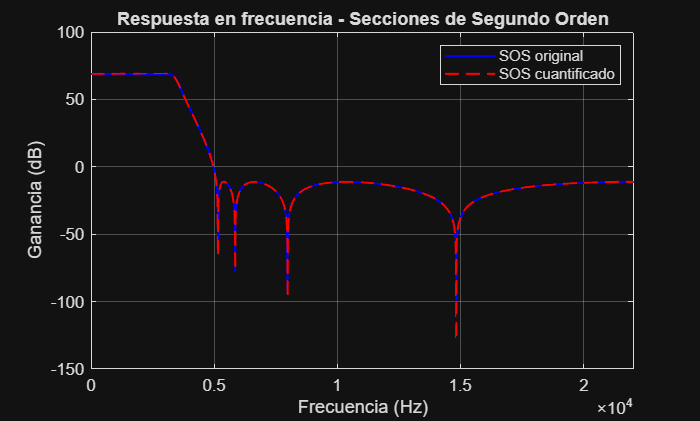

% sos_q contiene las Secciones de Segundo Orden cuantificadas

num = 50000;

% Respuesta en frecuencia del filtro original (SOS)
[H_sos, f] = freqz(sos, num, Fs);

% Respuesta en frecuencia del filtro SOS cuantificado
[H_sos_q, ~] = freqz(sos_q, num, Fs);

% Representación
figure;
plot(f, 20*log10(abs(H_sos)), 'b','LineWidth',1.2);
hold on;
plot(f, 20*log10(abs(H_sos_q)), 'r--','LineWidth',1.2);
grid on;

title('Respuesta en frecuencia - Secciones de Segundo Orden');
xlabel('Frecuencia (Hz)');
ylabel('Ganancia (dB)');
legend('SOS original', 'SOS cuantificado');

xlim([0 Fs/2]);

3. Raíces en Secciones de Segundo Orden

a) Calcule las raíces de cada Sección de Segundo Orden del filtro original obtenidas en el bloque anterior.

% Obtenemos las dimensiones de la matriz SOS (proporcionada por el bloque 2)
[L, ~] = size(sos);
ceros_originales = [];
polos_originales = [];

% Extraemos raíces de cada sección individualmente
for i = 1:L
    % Raíces del numerador [b0i, b1i, b2i]
    ceros_originales = [ceros_originales; roots(sos(i, 1:3))];
    % Raíces del denominador [1, a1i, a2i]
    polos_originales = [polos_originales; roots(sos(i, 4:6))];
end

% Vector total de raíces originales (polos + ceros) para comparación
raices_total_original = [ceros_originales; polos_originales];

% Ver los resultados
disp('--- CEROS ORIGINALES ---');

--- CEROS ORIGINALES ---


disp(ceros_originales);

  -0.5161 + 0.8565i
  -0.5161 - 0.8565i
   0.4206 + 0.9072i
   0.4206 - 0.9072i
   0.6721 + 0.7405i
   0.6721 - 0.7405i
   0.7418 + 0.6707i
   0.7418 - 0.6707i



disp('--- POLOS ORIGINALES ---');

--- POLOS ORIGINALES ---


disp(polos_originales);

   0.7253 + 0.0934i
   0.7253 - 0.0934i
   0.7552 + 0.2585i
   0.7552 - 0.2585i
   0.8004 + 0.3761i
   0.8004 - 0.3761i
   0.8526 + 0.4473i
   0.8526 - 0.4473i



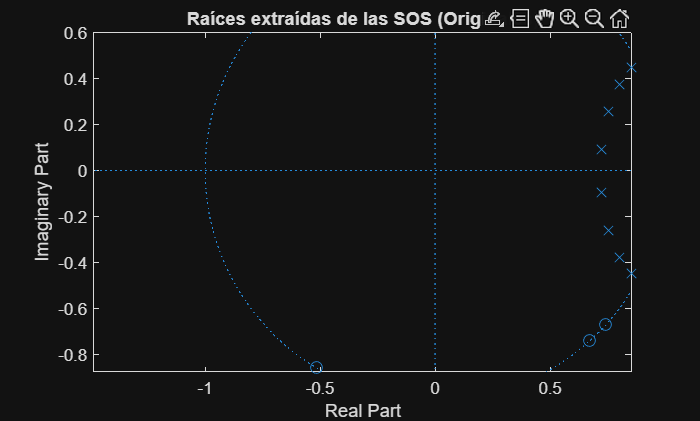


% Gráfico
figure('Name', 'Raíces Originales de las SOS');
zplane(ceros_originales, polos_originales);
title('Raíces extraídas de las SOS (Originales)');

b) Cuantifique cada una de las raíces con el mismo cuantificador empleado en los bloques anteriores (B = 16 bits, D = 8 bits).

% Definición del cuantificador según especificaciones (B=16, D=8)
q = quantizer('fixed', 'round', 'saturate', [16 8]);

% Cuantificación del vector de raíces (Paso a binario y reconversión a decimal)
raices_q_metodo3 = bin2num(q, num2bin(q, raices_total_original));

% Separamos ceros y polos cuantificados para el análisis gráfico
ceros_q_raices = raices_q_metodo3(1:length(ceros_originales));
polos_q_raices = raices_q_metodo3(length(ceros_originales)+1:end);
disp('Primeras 5 raíces cuantificadas (Parte Real + Imag):');

Primeras 5 raíces cuantificadas (Parte Real + Imag):


disp(raices_q_metodo3(1:5));

  -0.5156 + 0.8555i
  -0.5156 - 0.8555i
   0.4219 + 0.9062i
   0.4219 - 0.9062i
   0.6719 + 0.7422i



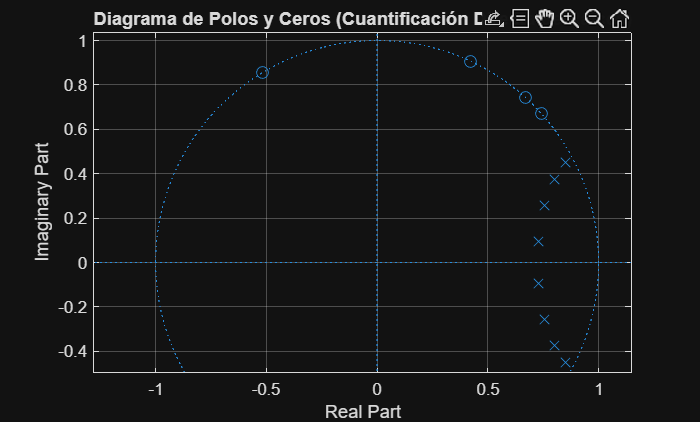


% Generar gráfica de este apartado
figure('Name', 'Apartado 3b: Raíces Cuantificadas');
zplane(ceros_q_raices, polos_q_raices);
title('Diagrama de Polos y Ceros (Cuantificación Directa de Raíces)');
grid on;

4. Análisis General

a) Calcule el error cuadrático medio (ECM) de las raíces (polos y ceros) de cada uno de los tres filtros cuantificados, con el filtro original. Indique el valor obtenido.

% 1. Definir la referencia (debe estar ordenada para comparar correctamente)
ref = sort(raices_total_original);
N_ref = length(ref);

% 2. Raíces del Filtro con Coeficientes Directos (C1)
r_directas = [roots(b_q); roots(a_q)];
% Si el tamaño no coincide, rellenamos con ceros hasta llegar a N_ref
if length(r_directas) < N_ref
    r_directas = [r_directas; zeros(N_ref - length(r_directas), 1)];
end
raices_q_directas_sorted = sort(r_directas);

% 3. Raíces del Filtro SOS Cuantificado (C2)
raices_q_sos_temp = [];
for i = 1:size(sos_q, 1)
    raices_q_sos_temp = [raices_q_sos_temp; roots(sos_q(i, 1:3)); roots(sos_q(i, 4:6))];
end
raices_q_sos_sorted = sort(raices_q_sos_temp);

% 4. Raíces Cuantificadas directamente (C3)
raices_q_metodo3_sorted = sort(raices_q_metodo3);

% --- Cálculo de ECM (ahora todos miden lo mismo y están ordenados) ---
ecm_metodo1 = (1/N_ref) * sum(abs(ref - raices_q_directas_sorted).^2);
ecm_metodo2 = (1/N_ref) * sum(abs(ref - raices_q_sos_sorted).^2);
ecm_metodo3 = (1/N_ref) * sum(abs(ref - raices_q_metodo3_sorted).^2);

fprintf('ECM Cuantificación Directa: %e\n', ecm_metodo1);

ECM Cuantificación Directa: 1.144586e+00


fprintf('ECM Cuantificación SOS: %e\n', ecm_metodo2);

ECM Cuantificación SOS: 7.016206e-01


fprintf('ECM Cuantificación de Raíces: %e\n', ecm_metodo3);

ECM Cuantificación de Raíces: 6.608503e-01


b) Analice las diferencias en la ganancia en función de la frecuencia (dB vs Hz) utilizando la función freqz con 50.000 puntos.

c) Analice las diferencias en la fase en función de la frecuencia utilizando la función unwrap.

d) Analice las diferencias en el diagrama de polos y ceros de los cuatro filtros empleando la función zplane. Exponga y justifique gráficamente las conclusiones.

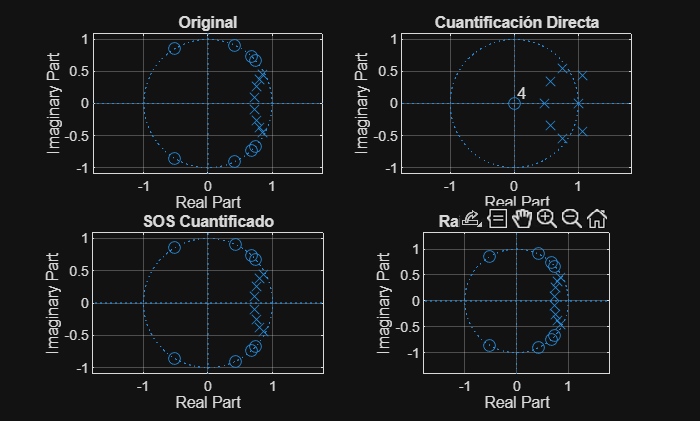

figure;
% 1. Filtro Original
subplot(2,2,1); zplane(ceros_originales, polos_originales);
title('Original'); grid on;

% 2. Cuantificación Directa
subplot(2,2,2); zplane(roots(b_q), roots(a_q));
title('Cuantificación Directa'); grid on;

% 3. SOS Cuantificadas
subplot(2,2,3);
c_sos_q = []; p_sos_q = [];
for i=1:size(sos_q,1)
    c_sos_q = [c_sos_q; roots(sos_q(i,1:3))];
    p_sos_q = [p_sos_q; roots(sos_q(i,4:6))];
end
zplane(c_sos_q, p_sos_q);
title('SOS Cuantificado'); grid on;

% 4. Raíces Cuantificadas
subplot(2,2,4); zplane(ceros_q_raices, polos_q_raices);
title('Raíces Cuantificadas'); grid on;